## PMDC Motor-State feedback-POSITION CONTROL

clc;
clear;
close all;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
tspan=[0,90];
x0=[0,0,0];
global A
A=[-(Ra/La) -(kb/La) 0;(kt/J) (-B_w/J) 0;0 1 0];
global B
B=[1/La ;0;0];
global B1
B1=[0;-1/J;0];
C=[0,0,1];
D=[0];
eig_val_A=eig(A)

eig_val_A =          0
   -1.1282
   -8.8728


controllability_matrix=ctrb(A,B)

controllability_matrix = 1.0e+03 *

    0.1000   -1.0000    9.0000
         0    0.0100   -0.1000
         0         0    0.0100


rank_CC = rank(controllability_matrix)

rank_CC = 3

p1=-5;
p2=-20;
p3=-10;
Kc=place(A,B,[p1,p2,p3])

Kc =     0.2500   33.9965  100.0000


T_load=0.0;
theta_ref=0.2

theta_ref = 0.2000

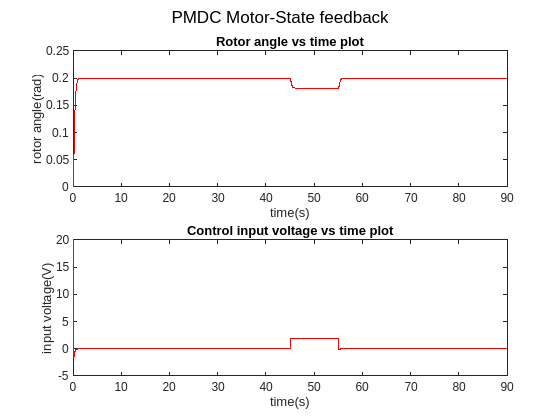

[t,x]=ode45(@(t,x) PMDC_feedback(t,x,[0;0;theta_ref],T_load,Kc),tspan,x0);
figure
hold on
sgtitle('PMDC Motor-State feedback')
subplot(2,1,1)
plot(t,x(:,3),'r')
xlabel('time(s)')
ylabel('rotor angle(rad)')
title('Rotor angle vs time plot')
subplot(2,1,2)
plot(t,Kc*[0;0;theta_ref]*ones(length(t),1)-x*Kc','r')
xlabel('time(s)')
ylabel('input voltage(V)')
title('Control input voltage vs time plot')
hold off

## PMDC Motor-LQR-POSITION CONTROL

clc;
clear;
close all;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
tspan=[0,90];
x0=[0,0,0];
global A
A=[-(Ra/La) -(kb/La) 0;(kt/J) (-B_w/J) 0;0 1 0];
global B
B=[1/La ;0;0];
global B1
B1=[0;-1/J;0];
C=[0,0,1];
D=[0];
eig_val_A=eig(A)

eig_val_A =          0
   -1.1282
   -8.8728


controllability_matrix=ctrb(A,B)

controllability_matrix = 1.0e+03 *

    0.1000   -1.0000    9.0000
         0    0.0100   -0.1000
         0         0    0.0100


rank_CC = rank(controllability_matrix)

rank_CC = 3

Q=[10 0 0 ;0 30 0;0 0 100];
R=10;
Kc=lqr(A,B,Q,R)

Kc =     3.0717   24.7625   10.0000


T_load=0.0;
theta_ref=1

theta_ref = 1

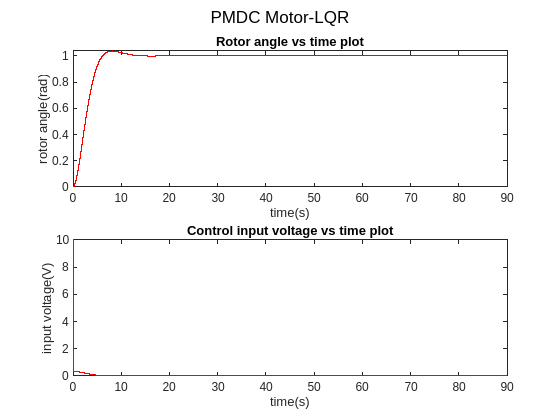

[t,x]=ode45(@(t,x) PMDC_feedback(t,x,[0;0;theta_ref],T_load,Kc),tspan,x0);
figure
hold on
sgtitle('PMDC Motor-LQR')
subplot(2,1,1)
plot(t,x(:,3),'r')
xlabel('time(s)')
ylabel('rotor angle(rad)')
title('Rotor angle vs time plot')
subplot(2,1,2)
plot(t,Kc*[0;0;theta_ref]*ones(length(t),1)-x*Kc','r')
xlabel('time(s)')
ylabel('input voltage(V)')
title('Control input voltage vs time plot')
hold off

function dx=PMDC_feedback(t,x,vol_input,load_torque,Kc)
global A
global B
global B1
if (t>45 && t<55)
    x=x+0.1*x;
else
    x=x;
end
dx=zeros(length(A),1);

dx=(A-B*Kc)*x+B*Kc*vol_input+B1*load_torque;
end